# Práctica N°2 Control Biológico.

Autor: Tomás Vidal

### Notas

Para esta práctica se considera el mismo problema que se tenía en la práctica N°1.

## Preguntas

- Por qué la matriz $A\left(\xi \right)$ se calcula haciendo el Jacobiano?

- Se puede entregar el livescript en vez de un .m y un pdf? o el livescript hecho pdf?

- ¿Por qué no se corresponde la derivación analítica con la modelación? (se espera que $\Omega_2$ no sea un parámetro de los polos del observador, pero lo es)

# Problemas/Incisos

- A) Analice la observabilidad del proceso reducido linealizado. Considere dos escenarios, uno don- de se cuenta con medición de la FCE y otro donde se cuenta con la medición de la concentra- ción de microorganismos.

- B) Tomando uno de los escenarios en que el proceso sea observable, diseñe un observador expo- nencial para estimar el/los estados no medidos. Diseñe tanto por Luenberger como por Kal- man.

- C) Simule los observadores en un proceso continuo, tanto con el modelo reducido como con el completo. Analice los resultados.

## Inciso A, observabilidad

Para analizar la observabilidad se emplea la matriz de observabilidad O (tiene que ser de rango completo para que sea observable).

     
$$O=$$

$$\matrix{L \cr L A(\xi) \cr LA^2(\xi)}$$


Para que O sea de rango completo, los vectores columna tienen que formar un espacio vectorial de orden 3.

### Matriz A

Para calcular $A\left(\xi \right)$ se considera el modelo en variable de estados.


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\dot{n} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
1 & 0 \\ 
-K_{s1} & -K_{s2} \\
-K_{N} & 0 \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]
- D * \left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]

$$


Cuyas matrices son referenciadas como $\hat{\xi} =K*r\left(\xi \;\right)+D*\xi \;$

Pero para poder trabajar con un modelo de 2x2 y que las cuentas sean más fáciles, como se va a trabajar en la fase de producción de plástico, donde el nitrógeno (n) debe ser nulo para poder darse, se elimina ese estado del sistema, además como en la producción de plástico la biomasa  es la misma, se podría considerar constante, por lo que también se elimina ese estado, resultado en el siguiente modelo de orden reducido:


$$
\left[
\begin{array}{c}
\dot{s} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
-K_{s1} & -K_{s2} \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
s \\ p
\end{array}
\right]
- D * \left[
\begin{array}{c}
s \\ p
\end{array}
\right]

$$


Se calcula A para este caso


$$A(\xi) = \left[
\begin{array}{c}
-K_{s1}\frac{dr_x}{ds}-D & -K_{s2}\frac{dr_x}{dp} \\
K_{p1}\frac{dr_p}{ds}  & \frac{dr_p}{dp}-D
\end{array}
\right] = 
\left[
\begin{array}{c}
-K_{s1}\frac{dr_x}{ds}-D & 0 \\
K_{p1}\frac{dr_p}{ds}  & -D
\end{array}
\right]$$


(calculé las derivadas a "mano")


$$A(\xi)=\left[
\begin{array}{c}
-K_{s1} (\frac{x\mu_{max}n}{K_n+n})(\frac{1}{K_s+s+\frac{s^2}{K_{is}}})(1-\frac{s-\frac{2s^2}{K_{is}}}{K_s+s+\frac{s^2}{K_{is}}}) -D & 0 \\
K_{p1}(q_{pmax}\frac{K_{ipn}}{K_{ipn}+n})(\frac{3s^2}{K_{ips}}+2s+K_{ps}) & -D
\end{array}
\right]$$


Considero que el estado que mido es el sustrato, por lo que tengo una matriz L = [1 0], entonces la matriz O es:


$$O=\left[
\begin{array}{c}
1 & 0 \\
-K_{s1} (\frac{x\mu_{max}n}{K_n+n})(\frac{1}{K_s+s+\frac{s^2}{K_{is}}})(1-\frac{s-\frac{2s^2}{K_{is}}}{K_s+s+\frac{s^2}{K_{is}}}) -D & 0 \\
\end{array}
\right]$$


Cuyo rango es 1, por lo que no sería observable, pero si tomo L = [0 1]


$$O=\left[
\begin{array}{c}
0 & 1 \\
K_{p1}(q_{pmax}\frac{K_{ipn}}{K_{ipn}+n})(\frac{3s^2}{K_{ips}}+2s+K_{ps}) & -D
\end{array}
\right]$$


Que sí es de rango 2, por lo que si es observable. Por lo que se podría medir el plástico, y estimar el sustrato.

## Inciso B, diseño de observadores

### Observador de Luenberger

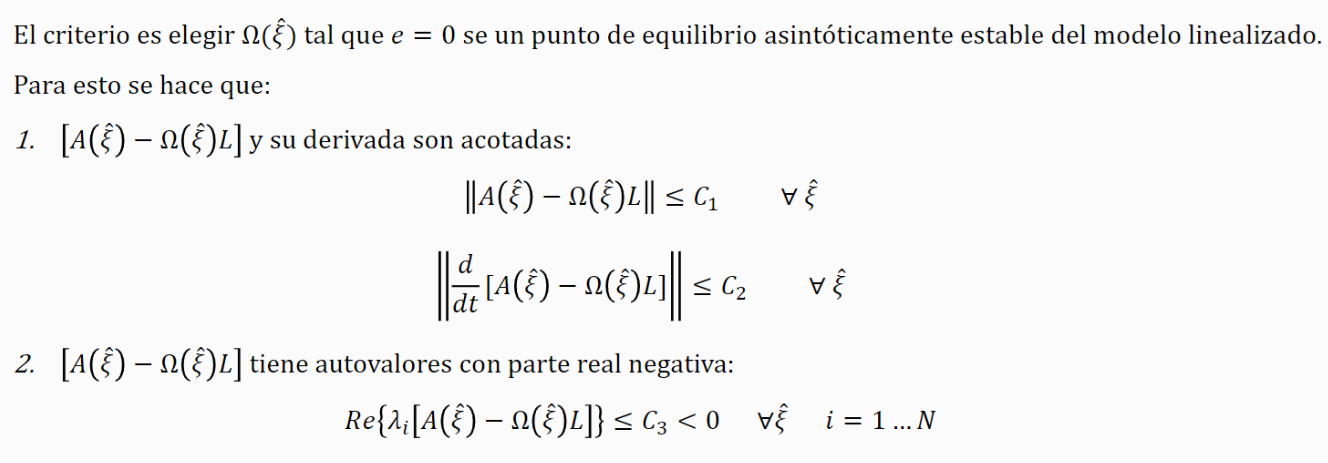

Si se cumplen 1 y 2 entonces el observador presenta estabilidad exponencial.

Se calculan los autovalores de $A\left(\hat{\xi} \right)-\Omega \left(\hat{\xi} \right)L$:


$$\left[
\begin{array}{c}
A_1 & 0 \\
A_2 & A_3 \\
\end{array}
\right]
-
\left[
\begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\end{array}
\right]
*
\left[
\begin{array}{c}
0 & 1
\end{array}
\right]
=
\left[
\begin{array}{c}
A_1 & -\Omega_1 \\
A_2 & A_3-\Omega_2 \\
\end{array}
\right]$$


De lo cual si se calculan los autovalores:


$$A_1 A_3 -A_1 \Omega {\;}_2 +A_2 \Omega {\;}_1 =0$$


Y si considero el caso cuando se tiene un batch, entonces $D=0$


$$\left(\frac{3\Omega_1 K_{\mathrm{P1}} q_{\mathrm{pmax}} }{K_{\mathrm{ips}} }\right)s^2 +2s+K_{\mathrm{ps}} =0$$


### Simulación de los polos del observador

% Se cargan los datos para el modelo
DatosModelo

Omega=[1;0];

a=(3*Omega(1)*kp1*qp_max)/(Kips);
b=2;
c=Kps;

sqrtTerm=sqrt(b*b-4*a*c);
pole1=(-b+sqrtTerm)/(2*a)

pole1 = -2.0507

pole2=(-b-sqrtTerm)/(2*a)

pole2 = -6.4406e+03

### Simulación de la estimación del sustrato

sim_hours = 20; % la cantidad de horas que se van a simular
timeStep = 0.01;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

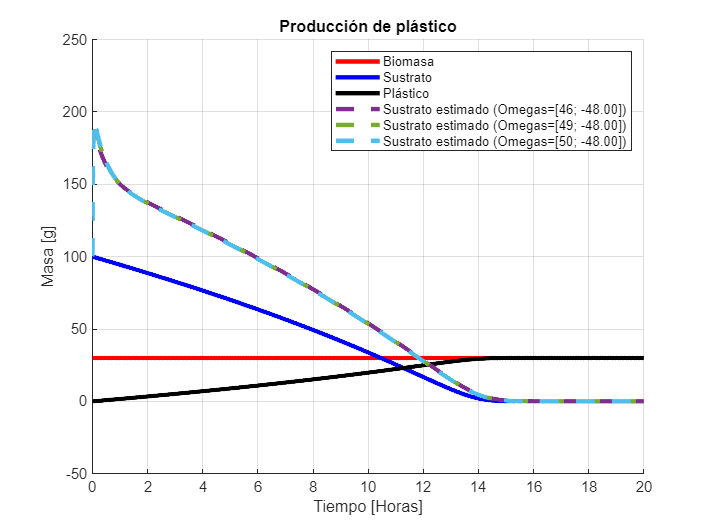

estimatedModelParameters.K = modelParameters.K(2:3, :);

x0=30;
s0=100;
n0=0;
p0=0;
xi_in = [x0; s0; n0; p0];
D=0;
L=[0 1];

Omegas={[46;-48], [49;-48], [50;-48]};

estimated_sustrate=cell(length(Omegas));
error=cell(length(Omegas));
MSE=cell(length(Omegas));
for i=1:length(Omegas)
    
    Omega=Omegas{i};

    sim_out = sim('TP2', simConfig);
    
    time = sim_out.tout;
    biomass = sim_out.x.Data;
    sustrate = sim_out.s.Data;
    nitrogen = sim_out.n.Data;
    plastic = sim_out.p.Data;
    mu = sim_out.mu.Data;
    qp = sim_out.qp.Data;
    volume = sim_out.v.Data;
    estimated_states = sim_out.estimated_states.Data;
    estimated_sustrate{i} = reshape(estimated_states(1,1,:), size(time));
    error{i}=(estimated_sustrate{i}-sustrate);
    MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Producción de plástico');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
ylim([-50 250])
plot(time, biomass.*volume, 'r', 'LineWidth', 3);
plot(time, sustrate.*volume, 'b', 'LineWidth', 3);
plot(time, plastic.*volume, 'k', 'LineWidth', 3);
plot(time, estimated_sustrate{1}.*volume, '--', 'LineWidth', 3);
plot(time, estimated_sustrate{2}.*volume, '--', 'LineWidth', 3);
plot(time, estimated_sustrate{3}.*volume, '--', 'LineWidth', 3);

legend('Biomasa', 'Sustrato', 'Plástico', ...
    sprintf('Sustrato estimado (Omegas=[%d; %.2f])', Omegas{1}(1), Omegas{1}(2)), ...
    sprintf('Sustrato estimado (Omegas=[%d; %.2f])', Omegas{2}(1), Omegas{3}(2)), ...
    sprintf('Sustrato estimado (Omegas=[%d; %.2f])', Omegas{3}(1), Omegas{2}(2)))

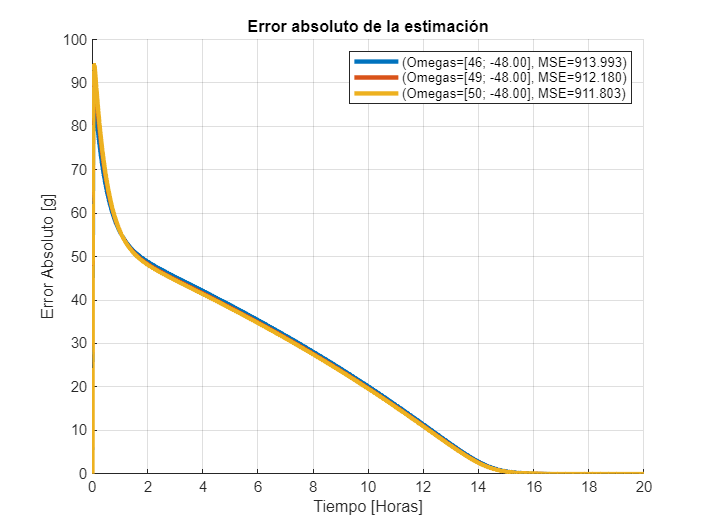


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error absoluto de la estimación');
xlabel('Tiempo [Horas]');
ylabel('Error Absoluto [g]');
plot(time, error{1}, 'LineWidth', 3);
plot(time, error{2}, 'LineWidth', 3);
plot(time, error{3}, 'LineWidth', 3);

legend(sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{1}(1), Omegas{1}(2), MSE{1}), ...
    sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{2}(1), Omegas{3}(2), MSE{2}), ...
    sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{3}(1), Omegas{2}(2), MSE{3}))

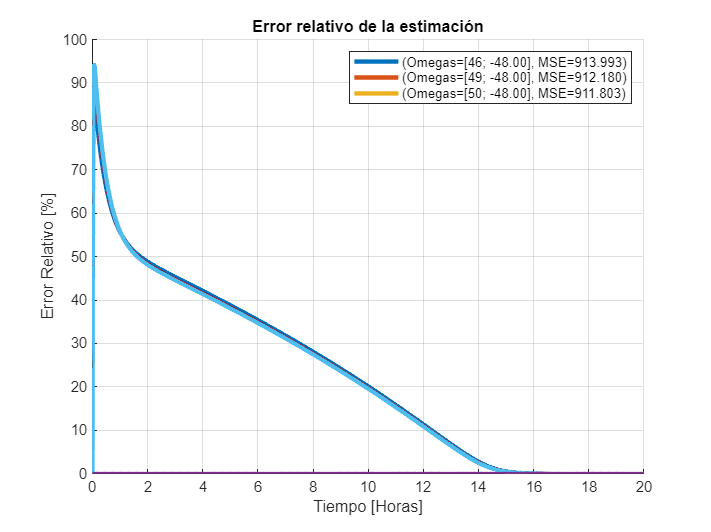


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo de la estimación');
xlabel('Tiempo [Horas]');
ylabel('Error Relativo [%]');
plot(time, error{1}*100/sustrate, 'LineWidth', 3);
plot(time, error{2}*100/sustrate, 'LineWidth', 3);
plot(time, error{3}*100/sustrate, 'LineWidth', 3);

legend(sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{1}(1), Omegas{1}(2), MSE{1}), ...
    sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{2}(1), Omegas{3}(2), MSE{2}), ...
    sprintf('(Omegas=[%d; %.2f], MSE=%.3f)', Omegas{3}(1), Omegas{2}(2), MSE{3}))

Analizo el contenido en frecuencia haciendo un modelo en variables de estados a partir de los datos del modelo.

% A=[-0.0000 -141.0330; 0 -200.0000];
% B= 1.0e-04 * [-0.1723; 0.4834];
% C=[-553.0954  390.0234];
% 
